# Delayed Feedback System for 2 DoF Manipulator

Add Path

clear;clc;
close all
addpath("Dynamics\")
addpath("..\")
addpath("..\ReadYAML\")
Robot=ReadYaml("Configuration\Jiang.yaml");
config=ReadYaml("Configuration\2DoF_Manipulator.yaml");

The system follows


$$M\left(\vec{q}\right) \ddot{\vec{q}} + C \left( \vec{q}, \dot{\vec{q}} \right) \dot{\vec{q}} + G \left( \vec{q} \right) = - K_{p} \left( \vec{q} - \vec{q}_{d} \right) - K_{d} \dot{\vec{q}} - f \left( \dot{\vec{q}} \right),$$


where friction follows the Stribeck model as


$$f(\dot{q}_{j})= \mathrm{sgn} \left( \dot{q}_{j} \right) \cdot \left[ F_{j}^{c} + F_{j}^{s} \exp{\left( - K_{j}^{s} \frac{\dot{q}_{j}}{V_{j}^{s}} \right)} \right] + F_{j}^{v} \dot{q}_{j}.$$


## Configurations

Sampling Time, Time Step & Simulation Time

% ts=config.ts;
ts=0.0201;
dt=config.ratio*ts;
SimulationTime=config.SimulationTime;
TimeSpan=0:dt:SimulationTime;

Initial Condition

TargetAngle=config.TargetAngle';
StateInitial=config.StateInitial';

Gains

Kp=diag(config.Kp);
Kd=diag(config.Kd);

Solver Option

option=ddeset('RelTol', config.DDE_RelTol, ...
    'AbsTol', config.DDE_AbsTol, ...
    "InitialStep",dt,"MaxStep",1.5*dt);

### Delayed Control Simulation

Controller

Controller=@(State)PDTorque(Kp,Kd,Robot,State,TargetAngle);

History Solution

history=@(t)get_HistorySolution(t,StateInitial);

Simulation

tic
sol=dde23(@(t,State,StateDelayed)DDE(t,State,Robot,"Sigmoid",StateDelayed,Controller),1.5*ts,history,TimeSpan,option);
toc

历时 641.190906 秒。


Show Time Steps

disp("Simulation time steps: "+num2str(length(sol.x)))

Simulation time steps: 186965


disp("Visualization time steps: "+num2str(length(TimeSpan)))

Visualization time steps: 248757


### Visualization for Delayed Control

Collect Data for Visualization

StateTimeHistoryDelay=deval(sol,TimeSpan,1:4);
eTimeHistoryDelay=StateTimeHistoryDelay(1:2,:)-TargetAngle;

$e-t$ Diagram

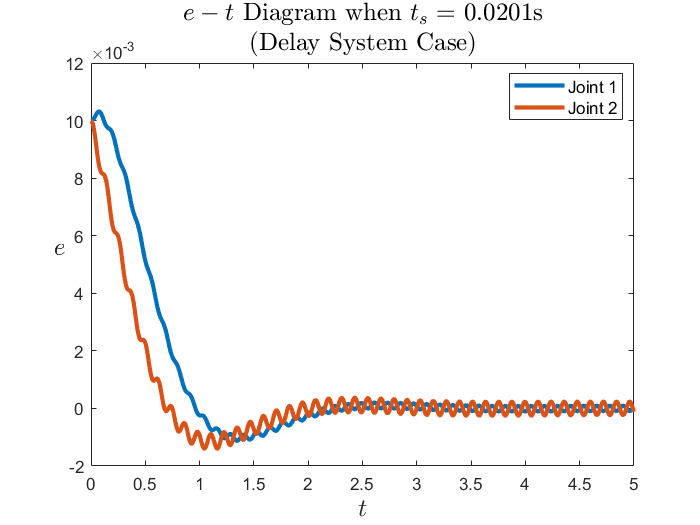

plot(TimeSpan,eTimeHistoryDelay,"LineWidth",2.5)
title(["$$ e-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Delay System Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$e$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Fontsize",10,"Location","best")

$\dot{e}-t$ Diagram

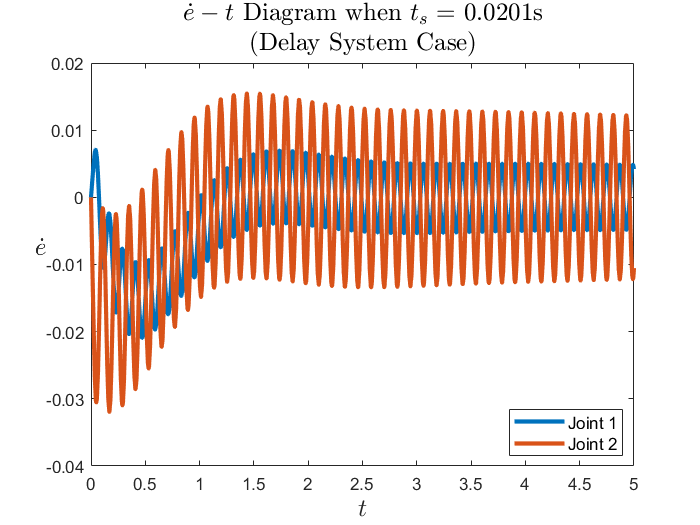

plot(TimeSpan,StateTimeHistoryDelay(3:4,:),"LineWidth",2.5)
title(["$$ \dot{e}-t $$ Diagram when $$t_s=$$ "+num2str(ts)+"s","(Delay System Case)"], ...
    "FontSize",15,"Interpreter","latex")
xlabel("$$t$$","FontSize",15,"Interpreter","latex")
ylabel("$$\dot{e}$$","FontSize",15,"Rotation",pi/2,"Interpreter","latex")
legend("Joint 1","Joint 2","Fontsize",10,"Location","best")